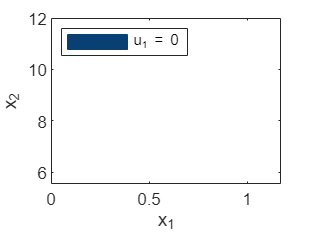

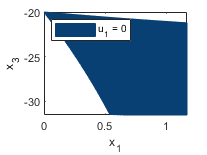

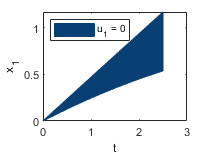

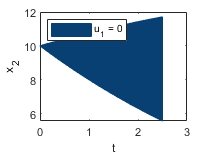

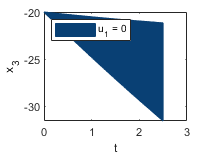

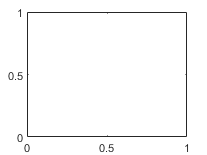

Index in position 1 exceeds array bounds. Index must not exceed 3.

Error in zonotope/project (line 31)
Z.Z = Z.Z(dims,:);

Error in reachSet/plotOverTime>aux_plotStandard (line 361)
        intX = interval(project(Rset{j},dims));

Error in 

% Visualization of Reachability Analysis-----------------------------------------------------------

% plot different projections
dims = {[1 2],[1,3]};
%dims = {[1 2 3]};
Rfault = [];
for i = 1:6
    Rfault = [Rfault,R{i}];
end

for fault = 1:6

    for k = 1:length(dims)
    
        figure; hold on; box on
        useCORAcolors("CORA:contDynamics")
        projDims = dims{k};
    
        % plot reachable sets
        %plot(R,projDims, 'DisplayName', 'Reachable set');
        useCORAcolors("CORA:contDynamics", 3)
         
%         plot(Rout, projDims, 'DisplayName', sprintf("Reachable set")); 
        %plot(Rin, projDims, 'DisplayName', sprintf("Reachable set inner-approximation")); 
        %plot(safeSet,projDims,'DisplayName', sprintf('Safe Set'));
    
        plot(Rfault(fault), projDims, 'DisplayName', ['u_{',num2str(fault),'} = 0']);
            
        % plot initial set
        % plot(R.R0,projDims,'DisplayName','Initial set');
    
        % plot simulation results
        % plot(simRes,projDims, 'DisplayName', 'Simulations');
%         plot(simResF(fault),projDims, 'DisplayName', 'Simulations w. fault');
    
        % label plot
        xlabel(['x_{',num2str(projDims(1)),'}']);
        ylabel(['x_{',num2str(projDims(2)),'}']);
    
        legend('Location', 'northwest')
    end

    for l = 1:3
        figure; hold on; box on
        useCORAcolors("CORA:contDynamics", 3)
    
%         plotOverTime(Rout, l, 'DisplayName', sprintf("Reachable set"));
        plotOverTime(Rfault(fault), l, 'DisplayName', ['u_{',num2str(fault),'} = 0']);
        % plotOverTime(simRes,l, 'DisplayName', 'Simulations');
%         plotOverTime(simResF(fault),l, 'DisplayName', 'Simulations w. fault');
        % label plot
        xlabel(['t']);
        ylabel(['x_{',num2str(l),'}']) ;
        legend('Location', 'northwest')
        
    end
end


clear  k l
%------------- END OF CODE --------------